# ECSE 343: Numerical Methods for Engineers- Assignment 1- part b

Due Date: 21st Feb. 2023

Student Name: Simon Li    

Student ID:    260984998

## Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

## Please submit this **.mlx** file along with the **PDF** copy of this file.

## Question 1: Cancellation Errors **(10 marks)**

a) Given the equation $x^2 + 2 bx  -1=0$ where $b$ is a parameter chosen such that $b> 0$. Using the quadratic formula the roots $x_1$ and $x_2$ of this equation are given by $x=-b\pm\sqrt{b^2 +1}$ . The following MATLAB program computes and plots the roots $x_1$ and $x_2$ as a function of $b$ for 1000 logarithmically spaced values of $b$ between ${10}^6$ and ${10}^8$. Run the code and explain the behavior shown in the plot. In particular, explain why the value computed for $x_1$ appears inaccurate for large values of $b$.

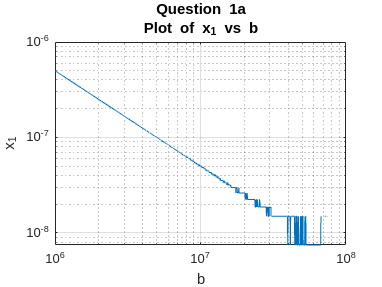



b = logspace(6,8,1000);

x1 = -b+sqrt(b.^2 +1);
x2 = -b-sqrt(b.^2 +1);



%plot x1 on a loglog scale

figure
loglog(b,x1)
title({'Question 1a';'Plot of x_1 vs b'})
xlabel('b')
ylabel('x_1')
grid on

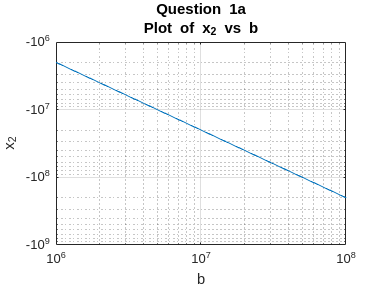



%plot x2 on a loglog scale

figure
loglog(b,x2)
xlabel('b')
ylabel('x_2')
title({'Question 1a';'Plot of x_2 vs b'})
grid on

b) Prove that the product of roots $x_1x_2=(-b+\sqrt{b^2 +1})(-b-\sqrt{b^2 +1})=-1$ for all $b> 0$.

*    % type up your solution here*

*since (a+b)(a-b) = a^2-b^2*

*x1x2 = (-b)^2-(b^2+1) = b^2-b^2-1 = -1*

c) Write a script that computes and plots the roots $x_1$ and $x_2$ as a function of $b$ for 1000 logarithmically spaced values of $b$ between ${10}^6$ and ${10}^8$ (same as in part a. above) which does not suffer from numerical illconditioning.

% write your program here 

b = logspace(6,8,1000);

%% Put your code for computing x1 and x2 below

x1 = zeros(size(b));
x2 = zeros(size(b));
for i=1:length(b)
    A = [1 b(i) b(i)^2; 1 1 b(i); 0 1 1];
    eig_values = eig(A);
    x1(i) = eig_values(1);
    x2(i) = eig_values(2);
end

%plot x1 on a loglog scale
figure(1)
loglog(b,x1)

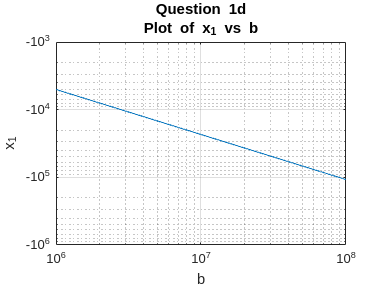

xlabel('b')
ylabel('x_1')
grid on
title({'Question 1d';'Plot of x_1 vs b'})


%plot x2 on a loglog scale
figure(2)
loglog(b,x2)

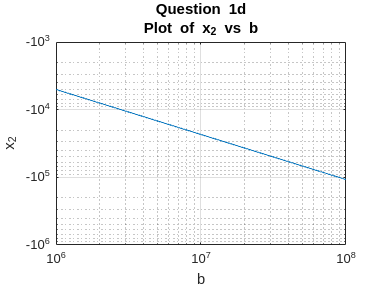

xlabel('b')
ylabel('x_2')
grid on
title({'Question 1d';'Plot of x_2 vs b'})

## Question 2:  Cholesky Least Squares Estimation **(10 marks)**

(a) **Cholesky factorization **is an alternative to LU decompostion which can be applied on symmetric positive definite matrices. A symmetric positive definite matrix$\mathit{\mathbf{M}}$must satisfy following two conditions:

     1. The matrix $\mathit{\mathbf{M}}$must be symmetric, i.e. $\mathit{\mathbf{M}}={\mathit{\mathbf{M}}}^{\mathit{\mathbf{T}}}$

     2. The matrix $\mathit{\mathbf{M}}$ must be positive definite,  i.e.  ${\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{M}}\;\mathit{\mathbf{x}}>0$ for  all  $\mathit{\mathbf{x}}\in \Re^{N\times 1}$, $\left\|\mathit{\mathbf{x}}\right\|\not= 0$.

If the above two conditons are met then the matrix $\mathit{\mathbf{M}}$ can be factored as 


$$\mathit{\mathbf{M}}=\mathit{\mathbf{L}}\;{\mathit{\mathbf{L}}}^T$$
                 

where $\mathit{\mathbf{L}}$ is a $N\times N$the lower triangular matrix with real and positive diagonal enteries. The enteries of matrix $\mathit{\mathbf{L}}$ are given by the following expression 


$$\textbf{L}_{i,j} = 
\begin{cases}
    \sqrt{ \textbf{M}_{j,j} - \sum_{k=1}^{j-1} \textbf{L}_{j,k}^2 }    ,& \text{if  } i =j\\
    \frac{1}{\textbf{L}_{j,j}} \left(\textbf{M}_{i,j} - \sum_{k=1}^{j-1} \textbf{L}_{i,k} \textbf{L}_{j,k} \right),              & \text{if  } i>j\\
0, & \text{otherwise}
\end{cases}$$


The cost of Cholesky factorization algorithm is rougly half than the LU decompostion. Your task is to implement the Cholesky decomposition alogorithm, the use the outline of the function named *CholeskyDecomposition* provided in the appendix.

Use the cell below to test your Cholesky decompostion code by computing the Frobenius norm of  $\left.{\left(\mathit{\mathbf{L}}\right.}^{\;} {\mathit{\mathbf{L}}}^T -M\right)\ldotp$

M= [2 -1 0; -1 2 -1; 0 -1 2];

L = CholeskyDecompositon(M);

Error =  norm(L*L'-M)

Error = 4.4409e-16

 b) In regression problems we ofthen need to solve the normal eqautions,  ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$.  Show that the matrix $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ is symmetric positive definite, and thus can be factored using Cholesky Decomposition.

*%type your answer here*

*since (AT*A)' = A' AT' = A'A, AT*A symmetric. *

Then a positive definite matrix is one for which `x' * M * x > 0` for all non-zero vectors `x`. Using this definition, we can show that `x' * (AT * A) * x = x' * AT * A * x > 0` for all non-zero vectors `x`. Since `A' * A` is positive definite, it follows that `AT * A` is also positive definite.

Since `AT * A` is symmetric positive definite, it can be factored using Cholesky decomposition. The Cholesky factorization of `AT * A` results in a lower triangular matrix `L` such that `AT * A = L * L'`. This factorization can be used to solve the normal equations efficiently by transforming the original problem into a triangular system of equations.

c) Using Cholesky facotrization scheme $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ can be factored as ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;={\mathit{\mathbf{L}}}^{\;} {\mathit{\mathbf{L}}}^T$. This transforms the normal equation into the form,


$$\mathit{\mathbf{L}}\;{\mathit{\mathbf{L}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$$


The above equation consists of the triangular systems. The solution **x **can be obtained by  first solving $\mathit{\mathbf{L}}\;\mathit{\mathbf{y}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$ using the forward substitution, then by solving the  ${\mathit{\mathbf{L}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{x}}=\mathit{\mathbf{y}}$ using backward subsitution. Implement the Cholesky solver function named *LeastSquareSolver_Cholesky  *for least squares in the function in the appendix.

Test the your Cholesky Least Saquare solver below.

A = rand(30,15); % random over-determined system
b = ones(30,1)

b =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



x = LeastSquareSolver_Cholesky(A,b);

residual = A*x-b;

Norm_residual = norm(residual);

disp(['Question 2c: The norm of the residual after solving using Cholesky based least sqaure solver is '  num2str(Norm_residual)]);

Question 2c: The norm of the residual after solving using Cholesky based least sqaure solver is 0.7211


## Question 3: Proofs **(10 marks)**

a) Show that the condition number of $A^TA$ is $\kappa \;\left(A^{T\;} A\right)={\kappa \left(A\right)}^2 \;$.

*% type your answer here*

*the norm of A transposed is the same as the norm of A.*

*The condition number is the norm of A times norm of A inverse.*

*Thus the condition number of A transpose times is equal to the condition number of A squared.*

b) Given two orthonormal matrices $U$and $Q$, show that product of these matrices, $\textrm{UQ}$, is also orthonormal.

*% type your answer here*

*since A*AT = I for orthonormal matrix A, then UQ*(UQ)T = UQ*QT*UT = U*UT = I. thus UQ is also orthonormal*

c) If A is an invertible matrix and Q is an orthonormal matrix, show that $\kappa \left(\textrm{QA}\right)=\kappa \left(A\right)\ldotp$

*% type your answer here*

*for orthonormal matrix A, AT = A'. Moreover, norm(A) = norm(A^-1)=1. Furthermore, the norm is 1. Thus k(QA) =  norm(QA) * norm((QA)^-1) = norm(A)*norm(A^-1) = k(A)*

## Question 4:  QR Decomposition **(10 marks)**

 In this question we will develop the different algorithms to implment QR factorization.

a)  Use the cell below to implement a function that computes Gram-Schmidt based QR decompositon of a input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

   A = rand(15,6); % A is a 15x6 matrix of random numbers
   [Qgs,Rgs] = gschmidt(A);
   
   %use the norm to check 
   normGS = norm(A-Qgs*Rgs,'fro') 

normGS = 4.4482e-16

b)  Use the cell below to implement a function that uses the Modiefied Gram-Schmidt approach to compute the  QR decompositon of  the input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

   A = rand(15,6); % A is a 15x6 matrix of random numbers
   [Qmgs,Rmgs] = mgschmidt(A);
   
   normMGS = norm(A-Qmgs*Rmgs,'fro')

normMGS = 4.6924e-16

## **Question 5:  Polynomial Fitting using Least Squares Estimation  (10 marks)**

Polynomial fitting is one of the many applications of Least-Squares Approximation. Given the experimental data, shown in Table below, 

    
$$\matrix{   Input,, x  | &  x_0  &x_1  & x_2& x_3 &\dots  & x_{m-1}& x_m \cr
Output, y| &  y_0 & y_1& y_2 & y_3 & \dots & y_{m-1}&y_m
}$$


we can fit a $n^{\textrm{th}}$degree polynomial, $p\left(x\right)=a_0 +a_1 x+a_{2\;} x^{2\;} +a_3 x^3 +\cdots +a_{n\;} x^n$. To find the coefficicients,  $\mathit{\mathbf{A}}=\left\lbrack a_{0\;} ,\;\;a_1 ,\;\;a_2 ,\cdots a_n \right\rbrack$, we can solve the linear system shown below. 


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^n \\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{a}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{Y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack } }$$


The system $\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{Y}}$ can then be solved to compute the coefficients in vector $\mathit{\mathbf{a}}\ldotp$

a) Your first task is to write a function that takes the input data vector $\mathit{\mathbf{x}}$ and degree of the polynomial, then returns the polynomial matrix $\mathit{\mathbf{M}}\ldotp$ Complete the function *PolynomialMatrix* in the appendix.

% test your code here by inputing X= [ 1 2 3] for degree 3. 

% You can manually verify if this matrix is implemented correctly.

X= [ 1; 2; 3];
Mtest = PolynomialMatrix(X,3)

Mtest =      1     1     1     1
     1     2     4     8
     1     3     9    27


b) The least squares method can be used to solve the overdetermined linear system $\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{Y}}$ to obtain the polynomial coefficients. This can be done by directly solving the Normal equations (using cholesky decomposition for example) or by using QR decomposition. In the code below, use the **MATALB's QR decomposition function** to find the polynomial coefficients if we assume a polynomial model of order 1. 

% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

x = x_given;
y = y_given;
deg = 1;

% get Polynomial Matrix 
Mp = PolynomialMatrix(x,deg);


   
   % MATLAB QR Decomposition
   [Q,R] = qr(Mp,0);
   
   % Find the polynomial coefficients using Q & R matrices obtained obove.

   % For forward and backward substitution functions use following
   % functions ForwardSubs(), BackwardSubs
     
  
   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
      Ar = BackwardSubs(R, Q'*y)

Ar =    -2.1670
   -3.7257


Now that you have obtained the coefficients for the first order polynomial model, $p\left(x\right)=a_0 +a_1 x$, we can test this model by evaluating $p\left(x\right)$ at different values of $x$ between 0 to 7. **Run the code below and explain the results obtained in the figure. Is this order sufficient?**

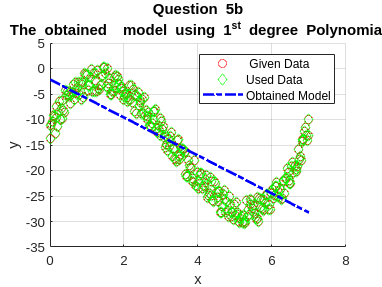

   xtest = x;
   
   px = zeros(length(xtest),1);
   powers = 0:deg;
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
   end
   %plots
    figure
   hold on
   plot(x,y,'ro')
 plot(x,y,'gd')
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' Given Data','Used Data','Obtained Model')
   grid on
   title({'Question 5b';'The obtained  model using 1^{st} degree Polynomial'})

%it's not sufficient, because this is like a linear regression (using the
%mse) to fit the curve.

c) In this part we will use a higher order model (a polynomial of order 6), but only a limited amount of input data points to generate this model (we will use only** 15 data points)**. Use QR decomposition function to find the polynomial coefficients for the **6th degree polynomial**.  

% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

deg = 6; %polynomial degree
x = x_given(1:20:end);  % x has 15 data points!! 
y = y_given(1:20:end);  % y has 15 data points!!

% get Polynomial Matrix 
Mp= PolynomialMatrix(x,deg);


   % MATLAB QR Decomposition
   [Q,R] = qr(Mp);
   
   %--------------------------------------------------------------------------------------------------
   % Find the polynomial coefficients using  Q & R matrices obtained obove.
   
   
   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
   Ar = R\Q'*y

Ar =   -14.0832
   35.0494
  -34.3004
   15.5398
   -3.8678
    0.4798
   -0.0227


We can test this model by evaluating $p\left(x\right)=a_{0\;} +a_1 x+\ldotp \ldotp \ldotp +a_6 x^6$ at different values of $x$ between 0 to 7. **Is this a good model? Comment on the results obtained in figure Question 5c, and explain the cause of what you see.**

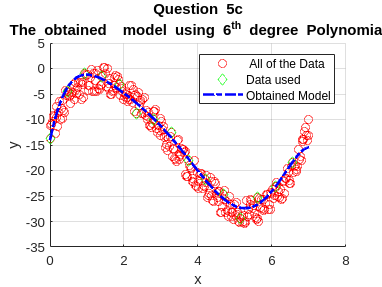


   xtest = linspace(0,7,701);
   xtest = xtest';
   powers = 0:deg;
   px = zeros(length(xtest),1);
 
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
      
   end
   %plots
   figure
   hold on
   plot(x_given,y_given,'ro') % plot all Data
   plot(x,y,'gd') % plot Used Data
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' All of the Data','Data used','Obtained Model')
   title({'Question 5c';'The obtained  model using 6^{th} degree Polynomial'})
   grid on

%This is a good model. it has higher flexibility in fitting more complex
%and non linear
%patterns such as the curve in 5c. It also seems to be more accurate in its
%prediciton

d ) In this part we will use a polynomial of order **14,**  again this will be used with limited amount of data (we will use only** 15 data points, same as part c**). Use QR decomposition function to find the polynomial coefficients for the **14th degree polynomial**.  

% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

deg =14

deg = 14

x = x_given(1:20:end);  % x has 15 data points!! 
y = y_given(1:20:end);  % y has 15 data points!!

% get Polynomial Matrix 
Mp= PolynomialMatrix(x,deg);


   % MATLAB QR Decomposition
   [Q,R] = qr(Mp);
   
   %--------------------------------------------------------------------------------------------------
   % Find the polynomial coefficients using  Q & R matrices obtained obove.
   
   
   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
   Ar = R\Q'*y

Ar = 1.0e+04 *

   -0.0014
   -0.1054
    0.6852
   -1.8101
    2.6740
   -2.5063
    1.5924
   -0.7123
    0.2288
   -0.0531


We can test this model by evaluating $p\left(x\right)$ at different values of $x$ between 0 to 7. **Is this a good model? Comment on the results obtained in figure Question 5d, and explain the cause of what you see.**

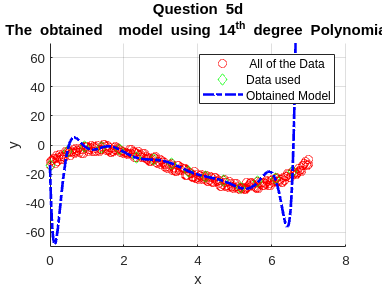


   xtest = linspace(0,7,701);
   xtest = xtest';
   powers = 0:deg;
   px = zeros(length(xtest),1);
 
   for I = 1:length(powers)
       px = px + Ar(I)*xtest.^powers(I);   
      
   end
   %plots
   figure('Name','Question 5d','NumberTitle','off')
   hold on
   plot(x_given,y_given,'ro') % plot all Data
   plot(x,y,'gd') % plot Used Data
   plot(xtest,px,'b-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   ylim([-70 70])
   legend(' All of the Data','Data used','Obtained Model')
 title({'Question 5d';'The obtained  model using 14^{th} degree Polynomial'})
   grid on


   %not very good. maybe the model is too complex at 14th degree. maybe
   %it's not very stable numerically too.


## Appendix 

## * Implement the Cholesky Decompositon fucntion here.*

function L =  CholeskyDecompositon(M)
if(size(M,1) ~= size(M,2))
    disp('Matrix M must be square!');
    
end
% L = zeros(size(M));
% Write your code here.
% Initialize L
n = size(M,1);
L = zeros(n,n);
% Perform Cholesky factorization
for i=1:n
    for j=1:i
        if (j == i)
            s = 0;
            for k=1:j-1
                s = s + L(j,k)^2;
            end
            L(j,j) = sqrt(M(j,j) - s);
        else
            s = 0;
            for k=1:j-1
                s = s + L(i,k)*L(j,k);
            end
            L(i,j) = (M(i,j) - s)/L(j,j);
        end
    end
end
end

## *Implement Least Square Solver for Cholesky here*

function x = LeastSquareSolver_Cholesky(A,b)
% get M = A^T A
M = A'*A;

% write your code here
% Step 1. Call the choesky function written in part (a) to get Lower triangular matrix,L
   % M = L L^T
n = size(M,1);
L = zeros(n,n);
% Perform Cholesky factorization
for i=1:n
    for j=1:i
        if (j == i)
            s = 0;
            for k=1:j-1
                s = s + L(j,k)^2;
            end
            L(j,j) = sqrt(M(j,j) - s);
        else
            s = 0;
            for k=1:j-1
                s = s + L(i,k)*L(j,k);
            end
            L(i,j) = (M(i,j) - s)/L(j,j);
        end
    end
end
% Step 2. Use the forward substitution function named  ForwardSubs() proivded in the appendix
b = A'*b;
n = size(L, 1);
y = zeros(n, 1);
y(1) = b(1) / L(1, 1);

for i = 2:n
    y(i) = (b(i) - L(i, 1:i-1) * y(1:i-1)) / L(i, i);
end
% Step 3. Use the backward substitution function BackwardSubs() proivded in the appendixh--
U = L';
n = size(U, 1);
X = zeros(n, 1);
X(n) = y(n) / U(n, n);

for i = n-1:-1:1
    X(i) = (y(i) - U(i, i+1:n) * X(i+1:n)) / U(i, i);
end
x = X;

end

## *Implement Polynomial Matrix here *

function M = PolynomialMatrix(x,n)
% write your code here
 % n is the degree of the polynomila
 % x is the vector of input data
 % Initialize matrix M with size (length(x), n+1)
    M = zeros(length(x), n+1);
    
    % Loop through each element in x
    for i = 1:length(x)
        % Loop through each column in M
        for j = 1:(n+1)
            % Compute the value for M(i,j)
            M(i,j) = x(i)^(j-1);
        end
    end
end


## *Implement QR Methods here*

- *Classical GramSchmidt *

function [Q,R] = gschmidt(A)
   % A is the input matrix- 
   % A could be a overdetermined matrix or a sqaure matrix
   % Q is orthonormal matrix 
   % R is the upper trianlgular matrix 
   
   % Write your code here.
   % Initialize the Q and R matrices
    [m, n] = size(A);
    Q = zeros(m, n);
    R = zeros(n, n);
%     R(1,1) = norm(A(1,:)');
%    Q(:,1) = A(:,1)/R(1,1);
%     for j = 2:m
%         P=0;
%         for i =1:j-1
%             R(i,j)=Q(i,:)*A(j,:)';
%             P=P+R(i,j)*Q(i,:);
%         end
%         V = A(j,:)-P;
%         R(j,j) = norm(V);
%         Q(j,:) = V/R(j,j);
%     end


    % Perform the Gram-Schmidt process
    for j = 1:n
        v = A(:, j);
        for i = 1:j-1
            R(i, j) = Q(:, i)' * A(:, j);
            v = v - R(i, j) * Q(:, i);
        end
        R(j, j) = norm(v);
        Q(:, j) = v / R(j, j);
    end
end

- *Modified Gram-Schimdt*


function [Q,R] = mgschmidt(A)
 % A is the input matrix- 
   % A could be a overdetermined matrix or a sqaure matrix
   % Q is orthonormal matrix 
   % R is the upper trianlgular matrix 
   
   % Write your code here.
   


    [m,n]=size(A);
    V=A;
    Q=zeros(m,n);
    R=zeros(n,n);
    for i=1:n
      R(i,i)=norm(V(:,i));  
      Q(:,i)=V(:,i)/R(i,i);
      for j=i+1:n
        R(i,j)=Q(:,i)'*V(:,j);
        V(:,j)=V(:,j)-R(i,j)*Q(:,i);
      end
    end

end

function X = BackwardSubs(U,y)
    % X is the vector
    % U is the upper triangular matrix
    
    n = size(U, 1);
    X = zeros(n, 1);
    X(n) = y(n) / U(n, n);
    
    for i = n-1:-1:1
        X(i) = (y(i) - U(i, i+1:n) * X(i+1:n)) / U(i, i);
    end
end

## *Function to generate Hilbert Matrix is provided here*

function A = Hilbert_matrix(size)

A = zeros(size,size);

for i=1:size
    for j=1:size
        A(i,j) = 1/(i+j-1);
    end 
end 
end